%abbiamo 3 diversi fattori di rischio che sono collegati
%perchè sono i tassi alle diverse maturità quindi non possono essere
%simulati indipendentemente.
%in t=0 diamo i parametri della curva
clc
clear all
close all
format bank
t_0=0;

%COSA CAMBIA AL VARIARE dei BETA??
beta_0=0.08; %valori di beta presi dall'esempio di Martellini
beta_1=-0.03;
beta_2=-0.01;
tau_1=3;
r= @(betaValues,tau,T) betaValues(1)...
    +betaValues(2)*((1-exp(-T/tau(1)))/(T/tau(1)))...
    +betaValues(3)*((1-exp(-T/tau(1)))/(T/tau(1))-exp(-T/tau(1)))...
    +betaValues(4)*((1-exp(-T/tau(2)))/(T/tau(2))-exp(-T/tau(2)));
%metto beta_3 = 0 e tau_2 = 1 così non influenzano il risultato
betaValues=[beta_0 beta_1 beta_2 0];
tau=[tau_1 1];

bond=[1, 1, 5, 10000, 0.05, 2];
zero=[1, 1, 0.5, 10000, 0, 2]; %capitalizzazione diversa da zero altrimenti errore, rimane uno zeroCouponBond perché coupon = 0% 
[~, D0bond, ~, ~]=fixed_duration(t_0, bond, r, tau, betaValues);
[~, D0zero, ~, ~]=fixed_duration(t_0, zero, r, tau, betaValues);
phiNS = - D0bond/D0zero

phiNS =          -8.66


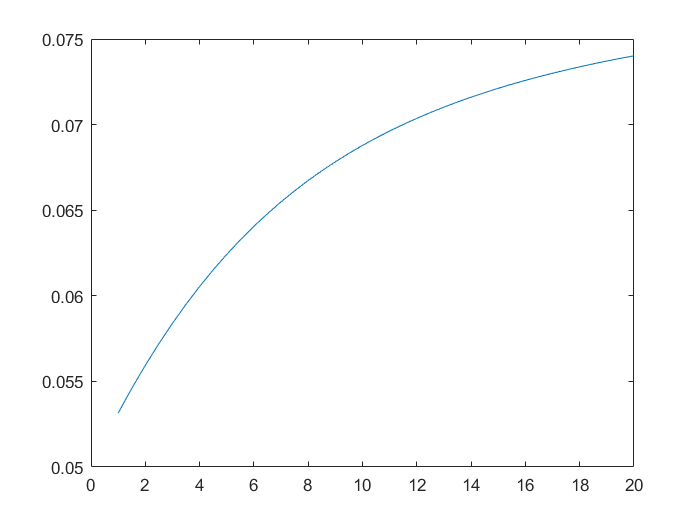



figure
maturities = 1:0.5:20;
tassi = zeros(1,length(maturities));
for i = 1:length(maturities)
    tassi(i) = r(betaValues,tau,maturities(i));
end
plot(maturities,tassi)


%Svensson ===> 4 fattori di rischio
beta_3=0.02;
tau_2=5;
betaValues=[beta_0 beta_1 beta_2 beta_3];
tau=[tau_1,tau_2];

%tau = [5,8];
bond=[1, 1, 5, 10000, 0.05, 2];
zero=[1, 1, 0.5, 10000, 0, 2]; %capitalizzazione diversa da zero altrimenti errore, rimane uno zeroCouponBond perché coupon = 0% 
[~, D0bond, ~, ~]=fixed_duration(t_0, bond, r, tau, betaValues);
[~, D0zero, ~, ~]=fixed_duration(t_0, zero, r, tau, betaValues);
phi = - D0bond/D0zero

phi =          -8.45


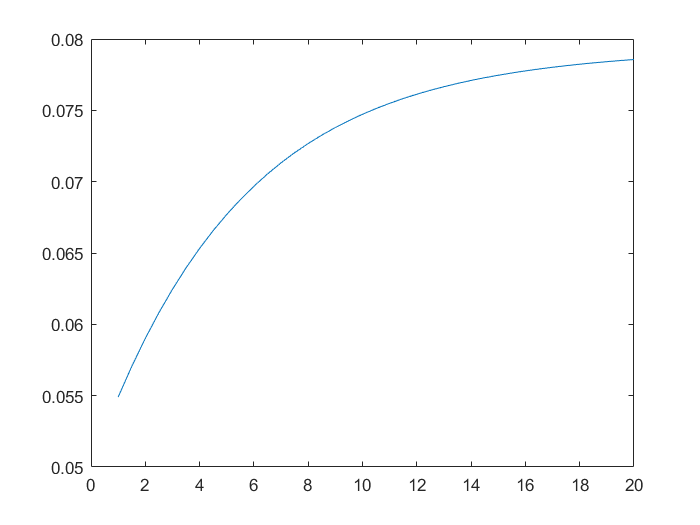

%[priceP, D0P, D1P, D2P, D3P]=fixed_duration(t_0, portfolio, r, tau, betaValues)

figure
maturities = 1:0.5:20;
tassi = zeros(1,length(maturities));
for i = 1:length(maturities)
    tassi(i) = r(betaValues,tau,maturities(i));
end
plot(maturities,tassi)


% priceZeroOriginal = priceZero;
% priceBondOriginal = priceBond;
% [priceBond, D0bond, D1bond, D2bond]=fixed_duration(t_0, bond, r, tau, betaValues+betaVariation);
% [priceZero, D0zero, D1zero, D2zero]=fixed_duration(t_0, zero, r, tau, betaValues+betaVariation);
% priceBond + phi*(priceZero-priceZeroOriginal);
% priceBondOriginal;

hedge = zero;
%variazione di beta_0
betaVariation = [0.08 0 0 0];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =           5.31


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =         -29.62


%variazione di beta_1
betaVariation = [0 -0.03 0 0];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =          -5.42


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =           6.97


%variazione di beta_2
betaVariation = [0 0 0.04 0];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =          -3.74


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =          -5.07


%variazione di beta_3
betaVariation = [0 0 0 0.09];
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =          -7.85


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =          -9.73


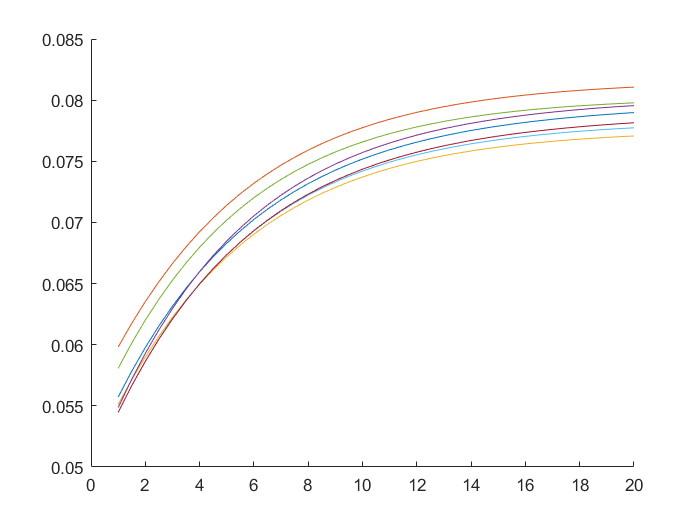


%priceBond+dot(phi,priceZero-priceZeroOriginal)

%PROVARE CON PIù ZERI

%struttura dei tassi per alcune variazioni dei beta
seed = 'default';
num_scenari = 7;
mu = zeros(1,4);
sigma = 0.001;
Sigma = eye(4)*(sigma^2);
rng(seed) % For reproducibility
betaVariation = mvnrnd(mu,Sigma,num_scenari);

figure
maturities = 1:0.5:20;
betaValues = [0.08,-0.03,-0.01,0.02];
for j = 1:size(betaVariation,1)
    hold on
    tassi = zeros(1,length(maturities));
    for i = 1:length(maturities)
        tassi(i) = r(betaValues+betaVariation(j,:),tau,maturities(i));
    end
    plot(maturities,tassi)
end

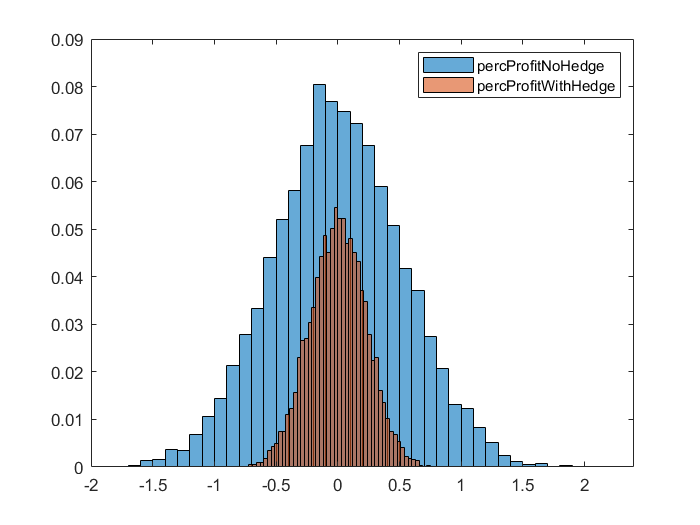

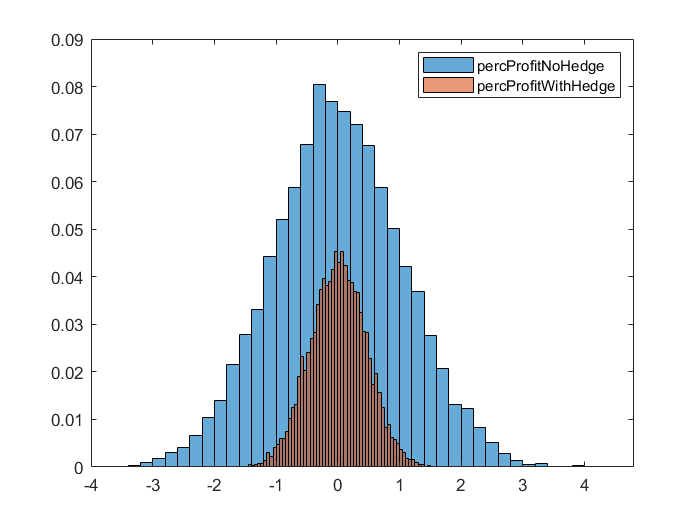

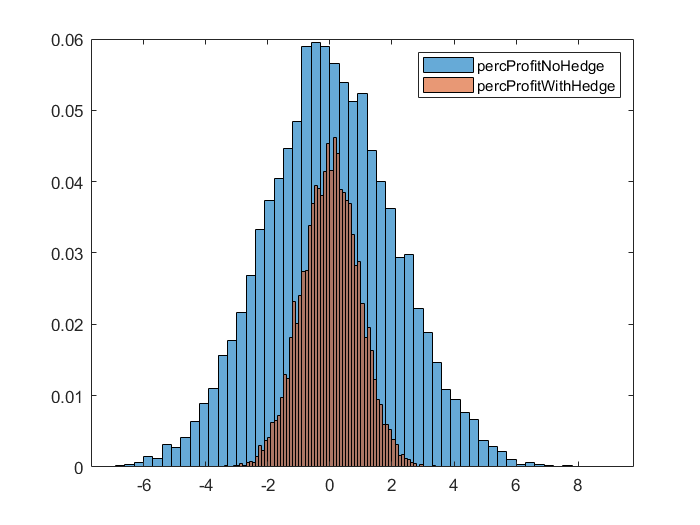


T=table('RowNames',{'VaR','VarNoHedge','CVaR','CVarNoHedge'});
probabilities = [0.90 0.95 0.99];
%proviamo con vari valori di deviazione standard
scale = [1,2,4];
tab = zeros(4,length(probabilities));
VaR = zeros(1,length(probabilities));
VaRNoHedge = zeros(1,length(probabilities));
CVaR = zeros(1,length(probabilities));
CVaRNoHedge = zeros(1,length(probabilities));
for diff = 1:length(scale)
    seed = 'default';
    num_scenari = 10000;%10000
    mu = zeros(1,4);
    sigma = 0.001*scale(diff);
    Sigma = eye(4)*(sigma^2);
    rng(seed) % For reproducibility
    betaVariation = mvnrnd(mu,Sigma,num_scenari);
    
    percProfit = zeros(num_scenari,1);
    percProfitNoHedge = zeros(num_scenari,1);
    for s = 1:num_scenari
        [newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation(s,:),phi);
        percProfit(s) = (newValuePosition-priceBondOriginal)/priceBondOriginal*100;
        percProfitNoHedge(s) = (priceBondNew-priceBondOriginal)/priceBondOriginal*100;
    end
    figure
    histogram(percProfitNoHedge,'Normalization','probability')
    hold on
    histogram(percProfit,'Normalization','probability')
    legend('percProfitNoHedge','percProfitWithHedge')
    hold off
    for prob=1:length(probabilities)
        id=floor(num_scenari*(1-probabilities(prob)));
        percProfit_sort = sort(percProfit);
        VaR(prob) = percProfit_sort(id);
        CVaR(prob) = mean(percProfit_sort(1:id));
        percProfitNoHedge_sort = sort(percProfitNoHedge);
        VaRNoHedge(prob) = percProfitNoHedge_sort(id);
        CVaRNoHedge(prob) = mean(percProfitNoHedge_sort(1:id));
    end
    tab(1,:) = VaR;
    tab(2,:) = VaRNoHedge;
    tab(3,:) = CVaR;
    tab(4,:) = CVaRNoHedge;
    
    T = addvars(T,tab,'NewVariableNames',num2str(sigma));
end

disp(T)

                            0.001                      0.002                      0.004         
                   _______________________    _______________________    _______________________

    VaR            -0.29    -0.37    -0.53    -0.59    -0.75    -1.06    -1.16    -1.48    -2.12
    VarNoHedge     -0.67    -0.86    -1.22    -1.34    -1.72    -2.41    -2.66    -3.40    -4.77
    CVaR           -0.40    -0.47    -0.60    -0.80    -0.94    -1.20    -1.59    -1.87    -2.40
    CVarNoHedge    -0.92    -1.07    -1.38    -1.83    -2.14    -2.74    -3.61    -4.22    -5.39




%%%%% PORTAFOGLIO CON PIù ELEMENTI

%consideriamo 3 bond diversi ===> 3 fattori di rischio
% b1=[2*12, 100, 0.05,1];
% b2=[7*12, 100, 0.05, 1];
% b3=[15*12, 100, 0.05, 1];
% B1=[1, 1, 2*12, 100, 0.05, 1];
% B2=[1, 1, 7*12, 100, 0.05, 1];
% B3=[1, 1, 15*12, 100, 0.05, 1];
% portfolio=[3, 1, 1, 1, b1, b2, b3];
%[price1, D01, D11, D21]=fixed_duration(t_0, B1, r, 3);
%[price2, D02, D12, D22]=fixed_duration(t_0, B2, r, 3);
%[price3, D03, D13, D23]=fixed_duration(t_0, B3, r, 3);

bond=[1, 1, 5, 10000, 0.05, 2];
[priceP, D0P, D1P, D2P, D3P]=fixed_duration(t_0, bond, r, tau, betaValues);

% bond=[5*12, 10000, 0.05, 2];
% zero=[0.5*12, 10000, 0, 2];
% portfolio=[2, 1, phi, bond, zero];
% [priceP, D0P, D1P, D2P]=fixed_duration(t_0, portfolio, r, tau, betaValues)

% %posso calcolarli con la funzione di prima
portfolio_sensitivities = [D0P;D1P;D2P;D3P];

%treasury bonds as hedging assets
% A1=[3*12, 100, 0.07, 1];
% A2=[7*12, 100, 0.08, 1];
% A3=[12*12, 100, 0.05, 1];
% A4=[18*12, 100, 0.06, 1];
% A1=[0.5*12, 10000, 0, 2];
% A2=[1.0*12, 10000, 0, 2];
% A3=[1.5*12, 10000, 0, 2];
% A4=[2.0*12, 10000, 0, 2];

asset_sentitivities = zeros(4);

% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A1], r, tau, betaValues);
% asset_durations(:,1) = [Dl, Ds, Dg, p];
% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A2], r, tau, betaValues);
% asset_durations(:,2) = [Dl, Ds, Dg, p];
% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A3], r, tau, betaValues);
% asset_durations(:,3) = [Dl, Ds, Dg, p];
% [p, Dl, Ds,Dg ]=fixed_duration(0, [1, 1, A4], r, tau, betaValues);
% asset_durations(:,4) = [Dl, Ds, Dg, p];

% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A1], r, tau, betaValues);
% asset_sentitivities(:,1) = [D_0, D_1, D_2, D_3];
% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A2], r, tau, betaValues);
% asset_sentitivities(:,2) = [D_0, D_1, D_2, D_3];
% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A3], r, tau, betaValues);
% asset_sentitivities(:,3) = [D_0, D_1, D_2, D_3];
% [p, D_0, D_1, D_2, D_3]=fixed_duration(0, [1, 1, A4], r, tau, betaValues);
% asset_sentitivities(:,4) = [D_0, D_1, D_2, D_3];
% phi = asset_sentitivities\(-portfolio_sensitivities)

A1=[1, 1, 0.5, 10000, 0, 2];
A2=[1, 1, 1.0, 10000, 0, 2];
A3=[1, 1, 1.5, 10000, 0, 2];
A4=[1, 1, 2.0, 10000, 0, 2];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A1, r, tau, betaValues);
asset_sentitivities(:,1) = [D_0, D_1, D_2, D_3];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A2, r, tau, betaValues);
asset_sentitivities(:,2) = [D_0, D_1, D_2, D_3];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A3, r, tau, betaValues);
asset_sentitivities(:,3) = [D_0, D_1, D_2, D_3];
[~, D_0, D_1, D_2, D_3]=fixed_duration(0, A4, r, tau, betaValues);
asset_sentitivities(:,4) = [D_0, D_1, D_2, D_3];

phi = asset_sentitivities\(-portfolio_sensitivities)

phi =         220.23
       -415.05
        353.46
       -115.46




%swap

fixed = true;
T = 5;
faceValue = 10000;
NPayments = 2;
last_rate = 0.05;
swap=[1, 1, T, faceValue, NaN, NPayments];
[p_swap,Dd_swap] = swap_duration(t_0, swap, r, tau, betaValues, fixed, last_rate)

p_swap =              0


Dd_swap =      -38127.71


% swap_duration(fixed, t_0, T, faceValue, NPayments, r, tau, betaValues, last_rate)

bond=[1, 1, 5, 10000, 0.05, 2];
[priceBond, D0bond, D1bond, D2bond]=fixed_duration(t_0, bond, r, tau, betaValues);
phi = - D0bond/Dd_swap

phi =          -1.08



betaVariation = [0.02 0 0 0];

hedge = swap;
[newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation,phi,'swap',fixed,last_rate);
percProfit = (newValuePosition-priceBondOriginal)/priceBondOriginal*100

percProfit =          -0.66


percProfitNoHedge = (priceBondNew-priceBondOriginal)/priceBondOriginal*100

percProfitNoHedge =          -8.49


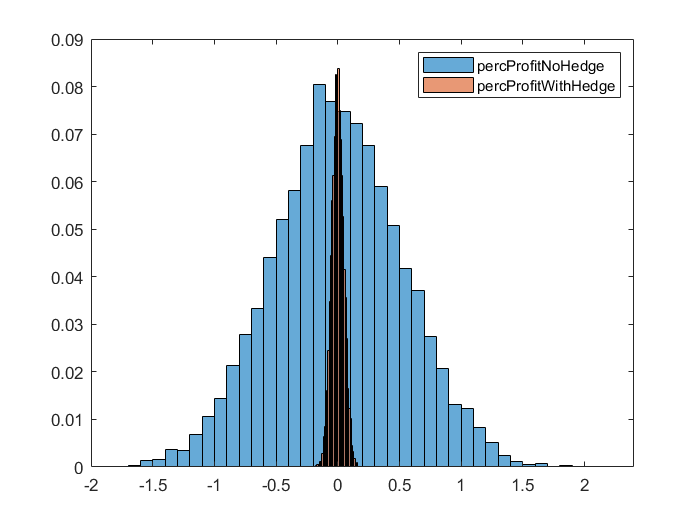

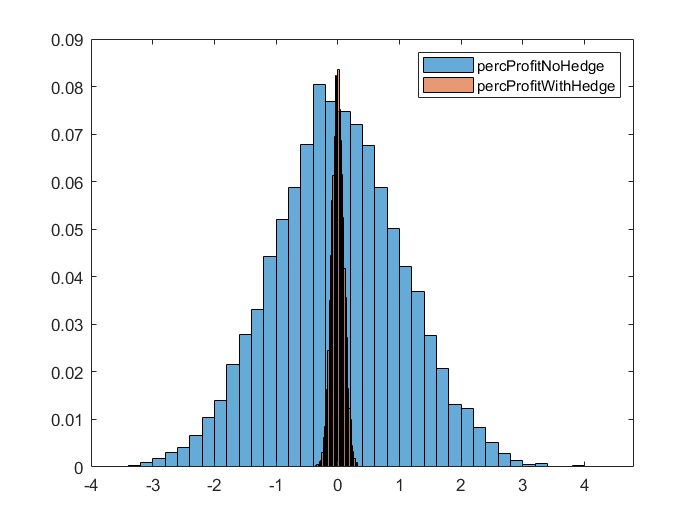

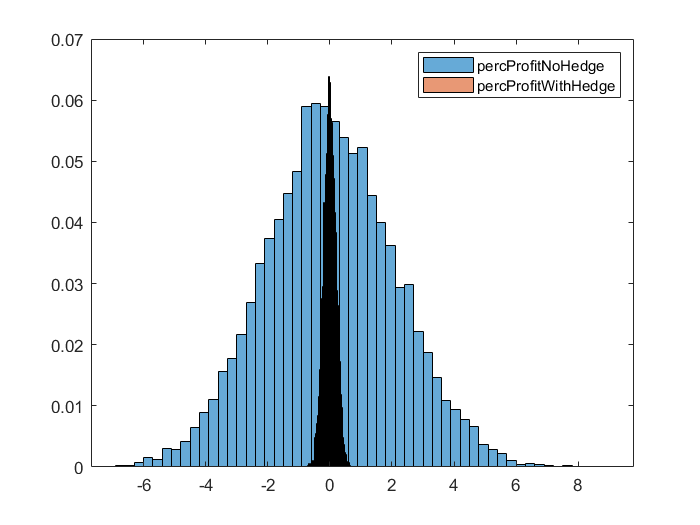

T=table('RowNames',{'VaR','VarNoHedge','CVaR','CVarNoHedge'});
for diff = 1:length(scale)
    seed = 'default';
    num_scenari = 10000;%10000
    mu = zeros(1,4);
    sigma = 0.001*scale(diff);
    Sigma = eye(4)*(sigma^2);
    rng(seed) % For reproducibility
    betaVariation = mvnrnd(mu,Sigma,num_scenari);
    
    percProfit = zeros(num_scenari,1);
    percProfitNoHedge = zeros(num_scenari,1);
    for s = 1:num_scenari
        [newValuePosition,priceBondOriginal,priceBondNew] = portfolioShock(t_0,bond,hedge,r,tau,betaValues,betaVariation(s,:),phi,'swap',fixed,last_rate);
        percProfit(s) = (newValuePosition-priceBondOriginal)/priceBondOriginal*100;
        percProfitNoHedge(s) = (priceBondNew-priceBondOriginal)/priceBondOriginal*100;
    end
    figure
    histogram(percProfitNoHedge,'Normalization','probability')
    hold on
    histogram(percProfit,'Normalization','probability')
    legend('percProfitNoHedge','percProfitWithHedge')
    hold off
    for prob=1:length(probabilities)
        id=floor(num_scenari*(1-probabilities(prob)));
        percProfit_sort = sort(percProfit);
        VaR(prob) = percProfit_sort(id);
        CVaR(prob) = mean(percProfit_sort(1:id));
        percProfitNoHedge_sort = sort(percProfitNoHedge);
        VaRNoHedge(prob) = percProfitNoHedge_sort(id);
        CVaRNoHedge(prob) = mean(percProfitNoHedge_sort(1:id));
    end
    tab(1,:) = VaR;
    tab(2,:) = VaRNoHedge;
    tab(3,:) = CVaR;
    tab(4,:) = CVaRNoHedge;
    
    T = addvars(T,tab,'NewVariableNames',num2str(sigma));
end

disp(T)

                            0.001                      0.002                      0.004         
                   _______________________    _______________________    _______________________

    VaR            -0.06    -0.08    -0.11    -0.12    -0.16    -0.23    -0.25    -0.32    -0.46
    VarNoHedge     -0.67    -0.86    -1.22    -1.34    -1.72    -2.41    -2.66    -3.40    -4.77
    CVaR           -0.09    -0.10    -0.13    -0.17    -0.20    -0.26    -0.34    -0.40    -0.52
    CVarNoHedge    -0.92    -1.07    -1.38    -1.83    -2.14    -2.74    -3.61    -4.22    -5.39

